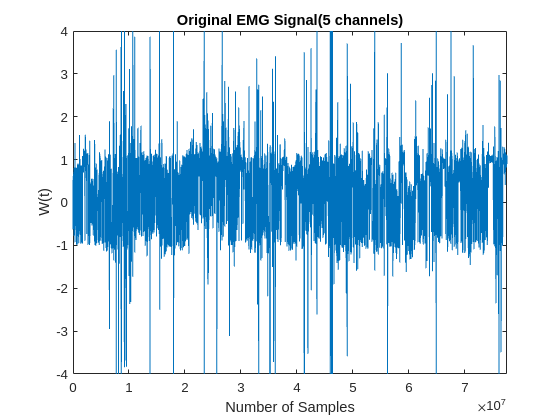

%addpath('C:\Users\igene\OneDrive - clarkson.edu\FullDataSet_PD-BioStampRC21\LABLE_02')
%load('label02.mat')
W={chID005Accel;chID007Accel;chID008Accel;chID014Accel;chID016Accel;chID018Accel;chID020Accel;chID022Accel;chID027Accel;chID030Accel;chID039Accel;chID043Accel;chID045Accel;chID058Accel;chID060Accel;chID062Accel};
emg4=cell2mat(Y);
emg4_data=emg4(2:end,end);
    for h=1:1:width(emg4_data)
        Fs = 1000; % Sampling frequency
        T = 1/Fs; % Sampling period
        L = length(emg4_data); % Length of signal
        t = (0:L-1)*T; % Time vector
        figure(1)
       plot(Fs*t(1:L),emg4_data)
        title('Original EMG Signal(5 channels)')
       xlabel('Number of Samples')
       ylabel('W(t)')
       axis ([0 L -inf inf])
        figure (2)
        plot(Fs*t(1:L),emg4_data(1:L,1))
       title('Original EMG Signal (single channel)')
        xlabel('Number of Samples')
       ylabel('W(t)')
        axis ([0 L -inf inf])
%Filtering 

        Fl=59/(Fs/2);       % 59hz lower cut-off frequency
        Fh=61/(Fs/2);       % 61hz higher cut-off frequency

        [b,a] = butter(4,[Fl, Fh],'stop'); 
        signal_filtered = filtfilt(b,a,emg4_data); %Notch filter


        signal_feq_filtered = fft(signal_filtered);  %Convert to frequency domain
        subplot(3,2,3)
        plot(Fs*t(1:L), signal_filtered)
        title('Time spectrum of the filtered EMG signal(9 channel)')
        xlabel('Time (s)')
        ylabel('Amplitude (\muV)')
        subplot(3,2,4)
        plot(Fs*t(1:L), signal_filtered(1:L,1))
        title('Time spectrum of the filtered EMG signal(single channel)')
        xlabel('Time (s)')
        ylabel('Amplitude (\muV)')
        p2=abs(signal_feq_filtered/L);
        p1=p2(1:floor(L/2+1));
        p1(2:end-1)=2*p1(2:end-1);
        f=Fs*(0:(L/2))/L;
        subplot(3,2,5)
        plot(f, p1)
        title('Frequency spectrum of the filtered EMG signal')
        xlabel('Frequency (Hz)')
        ylabel('Energy (\muV)')
%Windowing
        w_size = Fs * 0.5 ;          % The number of samples per 0.5s segment
        overlap = w_size/2;         % Create a 50% overlap
        n_win =floor(L/250 - 1);    % Number of windows per channel
%Features
         STD = zeros(n_win,10); 
         RMS = zeros(n_win,9); 
         SKE = zeros(n_win,9); 
         KUR = zeros(n_win,9); 
         MN = zeros(n_win,9); 
         VAR = zeros(n_win,9); 
         MAV = zeros(n_win,9); 
         HAM = zeros(n_win,9); 
         SAV = zeros(n_win,9); 
         ZCR = zeros(n_win,9); 
         
 
         w_start = 1;                % Start at the first sample
         w_end = w_size;             % End at window length
% 
         for n = 1:n_win
              STD(n, :) = std(signal_filtered(w_start:w_end, :));  % Standard Deviation  
              RMS(n, :) = rms(signal_filtered(w_start:w_end, :));   % Root Mean Square
              SKE(n, :) = skewness(signal_filtered(w_start:w_end, :)); % Skewness
              KUR(n, :) = kurtosis(signal_filtered(w_start:w_end, :)); % Kurtosis
              MN(n, :) = mean(signal_filtered(w_start:w_end, :)); %mean
              VAR(n, :) = var(signal_filtered(w_start:w_end, :)); %variance 
              MAV(n, :) = mean(abs(signal_filtered(w_start:w_end, :))); %absolute mean
              HAM(n, :) = harmmean(signal_filtered(w_start:w_end, :));  % harmmean 
              SAV(n, :) = sum(abs(signal_filtered(w_start:w_end, :))); %sum
              ZCR(n, :)= zerocrossrate(signal_filtered(w_start:w_end, :)); % zerocrossrate

             w_start = w_start + overlap;        
             w_end = w_start + w_size;
            
        end
         fea = [STD RMS SKE KUR MN VAR MAV HAM SAV ZCR];

         %Features in frequency domain

         STDF = zeros(n_win,9); 
         RMSF = zeros(n_win,9); 
         SKEF = zeros(n_win,9); 
         KURF = zeros(n_win,9); 
         MNF = zeros(n_win,9); 
         VARF = zeros(n_win,9); 
         MAVF = zeros(n_win,9); 
         HAMF = zeros(n_win,9); 
         SAVF = zeros(n_win,9); 
       
         
 
         w_start = 1;                % Start at the first sample
         w_end = w_size;             % End at window length
% 
         for n = 1:n_win
              STDF(n, :) = std(signal_feq_filtered(w_start:w_end, :));  % Standard Deviation  
              RMSF(n, :) = rms(signal_feq_filtered(w_start:w_end, :));   % Root Mean Square
              SKEF(n, :) = skewness(signal_feq_filtered(w_start:w_end, :)); % Skewness
              KURF(n, :) = kurtosis(signal_feq_filtered(w_start:w_end, :)); % Kurtosis
              MNF(n, :) = mean(signal_feq_filtered(w_start:w_end, :)); %mean
              VARF(n, :) = var(signal_feq_filtered(w_start:w_end, :)); %variance 
              MAVF(n, :) = mean(abs(signal_feq_filtered(w_start:w_end, :))); %absolute mean
              HAMF(n, :) = harmmean(signal_feq_filtered(w_start:w_end, :));  % harmmean 
              SAVF(n, :) = sum(abs(signal_feq_filtered(w_start:w_end, :))); %sum
             

             w_start = w_start + overlap;        
             w_end = w_start + w_size;
            
        end
         feaf = [STDF RMSF SKEF KURF MNF VARF MAVF HAMF SAVF ];
    end

    features_04 = [fea feaf];
     N4=normalize(features_04);
   %coeff1=pca(N);
   %L1=coeff1';
  % L1=features1;
 N4(:,end+1)=0;

  %L1(:,end+1)=1;
  
  
    %save("C:\Users\igene\OneDrive - clarkson.edu\FullDataSet_PD-BioStampRC21\Features\features02",'L02') % Saving each participants three frequency Band data in analysis1 folder
    